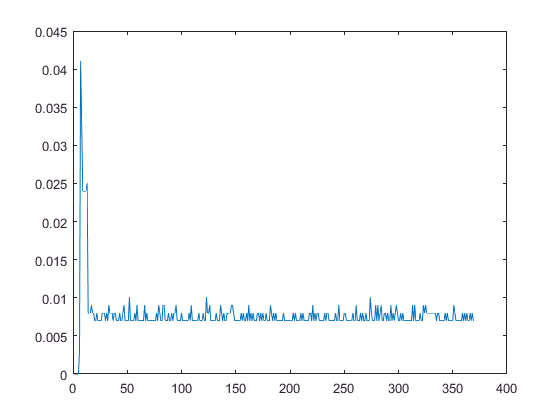

% GPS on channel 2, rest of the system on channel 1
data = importfile('system_gps.csv',7,inf);
plot(table2array(data(:,3)))

i_sys_avg_without_gps = mean(table2array(data(15:end,3)))

i_sys_avg_without_gps = 0.0075

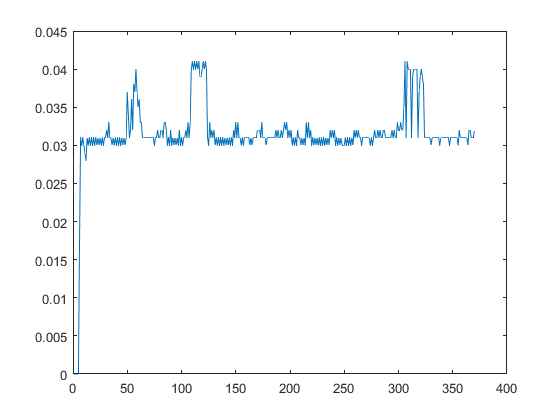

plot(table2array(data(:,5)))

i_avg_gps = mean(table2array(data(15:end,5)))

i_avg_gps = 0.0319

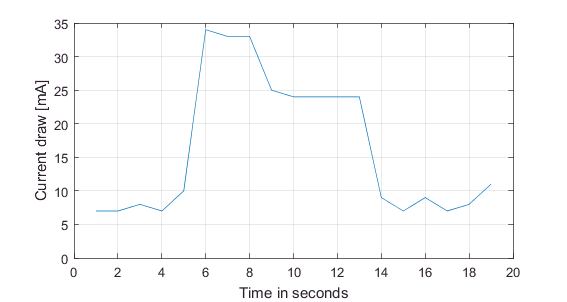

% GPS on channel 2, rest of the system on channel 1
% no external antenna
data = importfile('system_gps_no_ext.csv',7,inf);
hold on

clf
figure('PaperUnits','centimeters','PaperSize',[15,8],'Units','centimeters','Position',[2,2,15,8],'RendererMode','manual','Renderer','painters');
plot(table2array(data(3:20,3)).*1000)
grid on
xlabel 'Time in seconds'
ylabel 'Current draw [mA]'
saveas(gcf,'start_current','pdf');

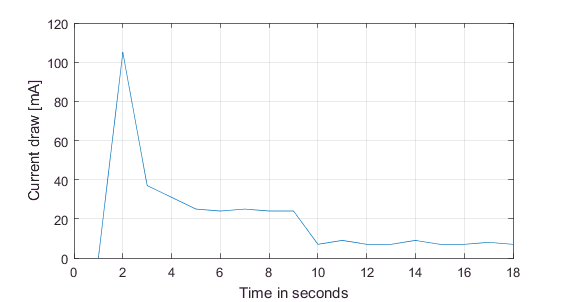

hold off

i_sys_avg_without_gps = mean(table2array(data(10:140,3)))

i_sys_avg_without_gps = 0.0077

% plot(table2array(data(:,5)))
i_avg_gps_no_antenna = mean(table2array(data(10:140,5)))

i_avg_gps_no_antenna = 0.0220

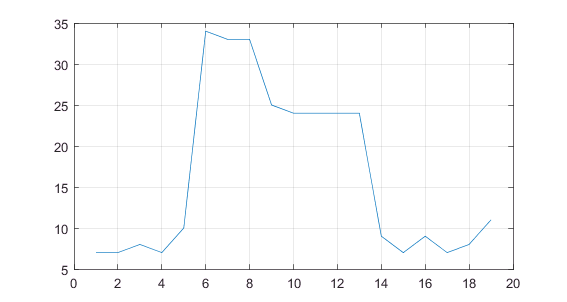

% GPS on channel 2, rest of the system on channel 1
data = importfile('system_gps_trigger.csv',7,inf);
hold on

clf
figure('PaperUnits','centimeters','PaperSize',[15,8],'Units','centimeters','Position',[2,2,15,8],'RendererMode','manual','Renderer','painters');
plot(table2array(data(2:20,3)).*1000)
grid on
ylim([0 35])
xlabel 'Time in seconds'
ylabel 'Current draw [mA]'
saveas(gcf,'send_current','pdf');

hold off

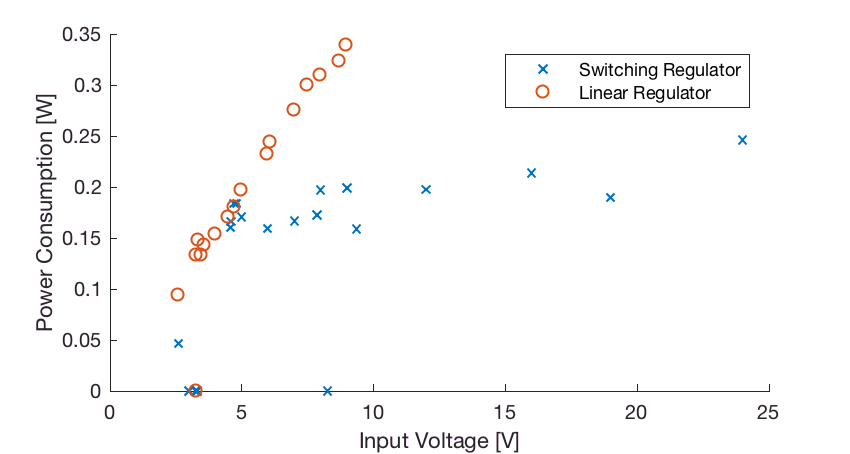


% using switching regulator to power system
data_switching = importfile('system_switching_regulator.csv',7,inf);
data_linear = importfile('system_linear_voltage.csv',7,inf);

keys_switching = unique(table2array(data_switching(:,2)));
values_switching = zeros(size(keys_switching));
for n = 1:size(keys_switching)
    i = data_switching(data_switching.VarName2 == keys_switching(n),3);
    values_switching(n) = mean(table2array(i));
end
keys_linear = unique(table2array(data_linear(:,2)));
values_linear = zeros(size(keys_linear));
for n = 1:size(keys_linear)
    i = data_linear(data_linear.VarName2 == keys_linear(n),3);
    values_linear(n) = mean(table2array(i));
end

clf
figure('PaperUnits','centimeters','PaperSize',[15,8],'Units','centimeters','Position',[2,2,15,8],'RendererMode','manual','Renderer','painters');
scatter(keys_switching,keys_switching.*values_switching,'x');
hold on
scatter(keys_linear,keys_linear.*values_linear);
legend("Switching Regulator","Linear Regulator")
ylabel 'Power Consumption [W]'
xlabel 'Input Voltage [V]'
hold off

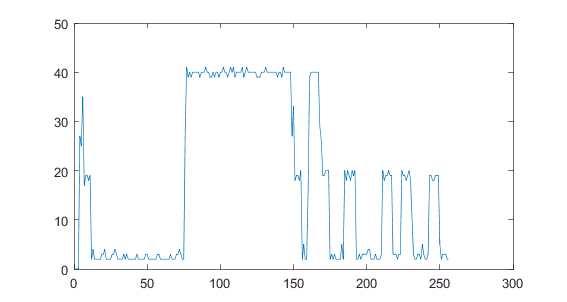

data = importfile('system_bluetooth.csv',7,inf);
hold on

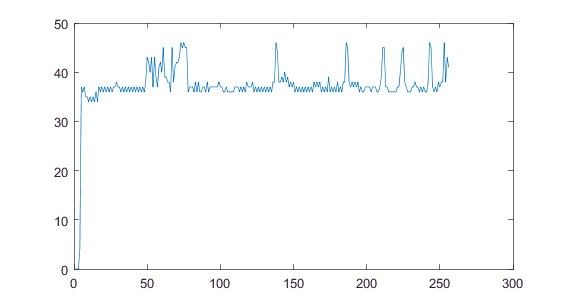

clf
figure('PaperUnits','centimeters','PaperSize',[15,8],'Units','centimeters','Position',[2,2,15,8],'RendererMode','manual','Renderer','painters');
plot(table2array(data(:,3)).*1000)

plot(table2array(data(:,5)).*1000)
bluetooth_connected = mean(table2array(data(16:73,5)).*1000)

bluetooth_connected = 2.3793

bluetooth_disconnected = mean(table2array(data(79:147,5)).*1000)

bluetooth_disconnected = 39.9130

hold off

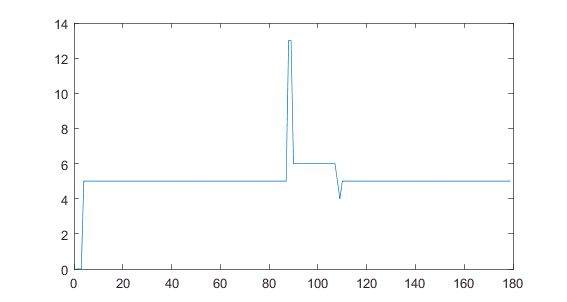

data = importfile('system_btle_bare.csv',7,inf);
hold on
clf
figure('PaperUnits','centimeters','PaperSize',[15,8],'Units','centimeters','Position',[2,2,15,8],'RendererMode','manual','Renderer','painters');
plot(table2array(data(:,3)).*1000)

plot(table2array(data(:,5)).*1000)
bluetooth_connected = mean(table2array(data(16:73,5)).*1000)

bluetooth_connected = 8.8793

bluetooth_disconnected = mean(table2array(data(60:130,5)).*1000)

bluetooth_disconnected = 10

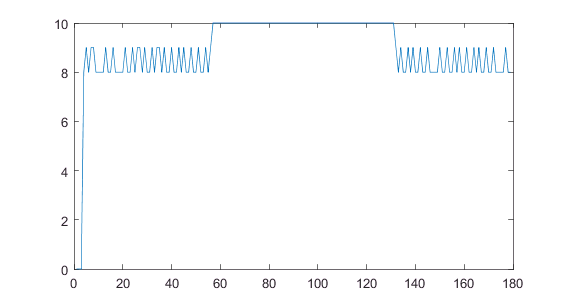

hold off